Lab Group n: Theodore Janson (260868223)

Lab Assignment 1

ECSE 403: Fall 2020

Professor Caine

September 25th 2020 

*The  goal of this lab is to model and control an inverted pendulum system. In that system the input is applied to a DC motor connected to a cart-pole. The first step to model the whole system is to model the DC motor. The equation of motion of a DC motor can be described by: *

Constants					

Jm = 0.01; %kgm^2 , inertia of the rotor and shaft
b = 0.001; %Nmsec , viscous friction coefficient
Ke = 0.02; %Vsec  , back emf constant
Kt = 0.02; %Nm/A  , motor torque constant
Ra = 10;   %Ω     , armature resitance


*1. Find the transfer function between the input voltage and the speed of the motor shaft( w(s) , va (s) where w(s) = θ'(s)).(Plug in the coefficients above). [10 marks] *

Using the coefficients for  θ' and va, 

a1 = (b+(Kt*Ke)/Ra)/Jm; %divide equation Jm to get unity coefficient for θ''
b0 = Kt / (Ra*Jm);

We can then define the transfer function using polynomial coefficients: 

G1 = tf([b0], [1 a1]) %a1 is the coefficient of w(t)


G1 =
 
     0.2
  ---------
  s + 0.104
 
Continuous-time transfer function.



*2. Using transfer function derived above and matlab, find the steady-state and time constant of the response of the motor to a step function. [10 marks]*

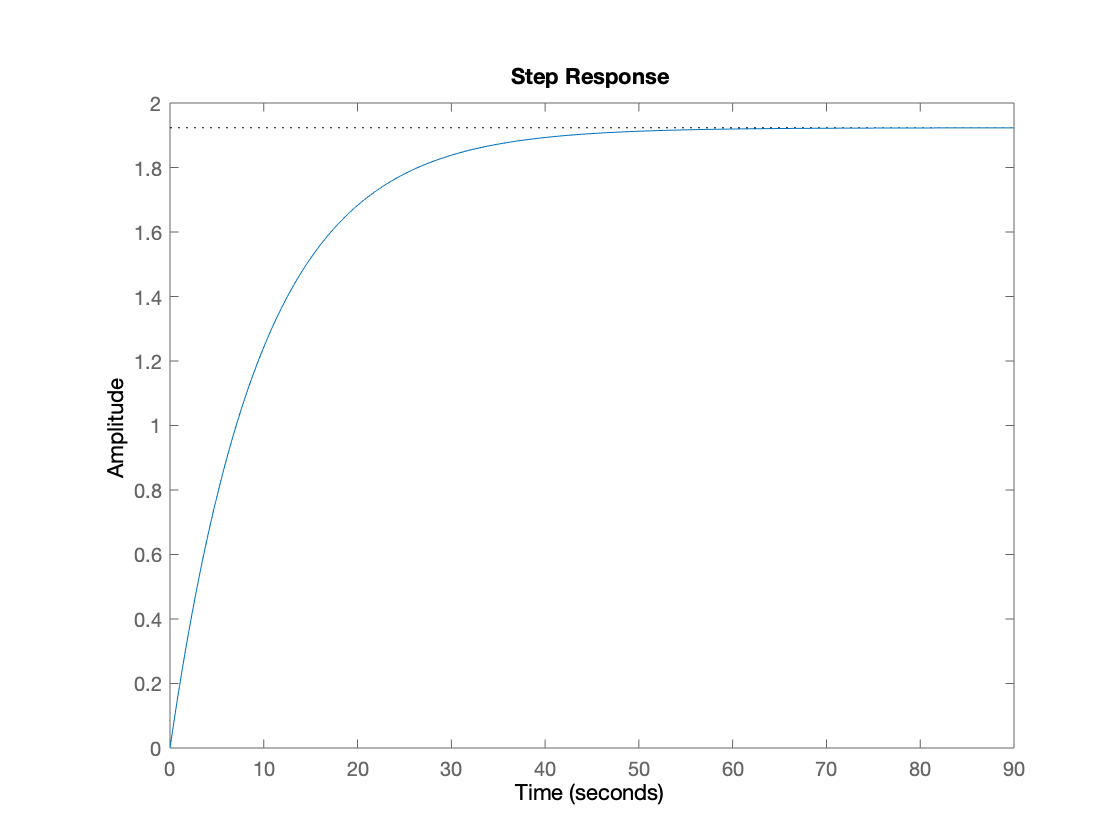

%s = tf('s');
stepplot(G1)

T = step(ss(G1));
SS_experimental = T(length(T), 1)

SS_experimental = 1.9228

Value_at_Time_Constant = (1-1/exp(1))*SS_experimental

Value_at_Time_Constant = 1.2155


Time_constant=max(find(abs(T-SS_experimental)>= Value_at_Time_Constant))

Time_constant = 10

Using the transfer function, we can then define the steady state and time coefficient to a step response: 

*3. Using previous step response find rise time and settling time of the system. [10 marks] 			*

Rise_time = stepinfo(G1).RiseTime

Rise_time = 21.1251

Settling_time = stepinfo(G1).SettlingTime

Settling_time = 37.6161

*4. Using Final Value Theorem, calculate the steady state speed of the motor to step response theoretically. Compare theoretical value and values you found in matlab. 		*

We can calculate the steady state speed manually using Final Value Theorem formula: f(inf) = lim(sF(s)) for s -> 0

Let W(s) = G1(s) x Va(s). Since limits of transfer functions cannot be computed directly in matlab, G1 is redefined as G using symbol s, and limit is computed. 

syms s
Va = 1/s;
G = b0 / (s + a1);
W = G * Va;
SS_theoretical = double(limit(W*s, s, 0))

SS_theoretical = 1.9231

5. Find the transfer function between the shaft’s angel and input voltage (θ(s)/v(s)). (Identify the order of the system with respect to new definition of input-output signals) [10 marks] 	

New coefficients are defined for the system: 

a0 = 0;

We can again define the transfer function using polynomial coefficients: 

G2 = tf([b0], [1 a1 a0])


G2 =
 
       0.2
  -------------
  s^2 + 0.104 s
 
Continuous-time transfer function.



Which constitutes a second order system. 

*6. Consider the transfer function in question 1. Apply a unity feedback loop to the system and find the closed loop transfer function [10 marks]. 	*

We can find the closed loop transfer function of the system using unity feedback with H = G / ( 1 + G) 

%H1 = G1 / (1+G1)
H1 = feedback(G1, 1)


H1 =
 
     0.2
  ---------
  s + 0.304
 
Continuous-time transfer function.



*7. Suppose a proportional controller is added to the system such that open-loop transfer function has changed from G(s) to K.G(s). Plot the step response of the closed loop unity feedback system choosing K = {0.1, 1, 10, 100}, in one figure. Describe the effect of proportional gain on step response’s behavior [15 marks]. 	*											

K = [0.1 1 10 100];

h1 = feedback(G1*K(1,1), 1)


h1 =
 
    0.02
  ---------
  s + 0.124
 
Continuous-time transfer function.



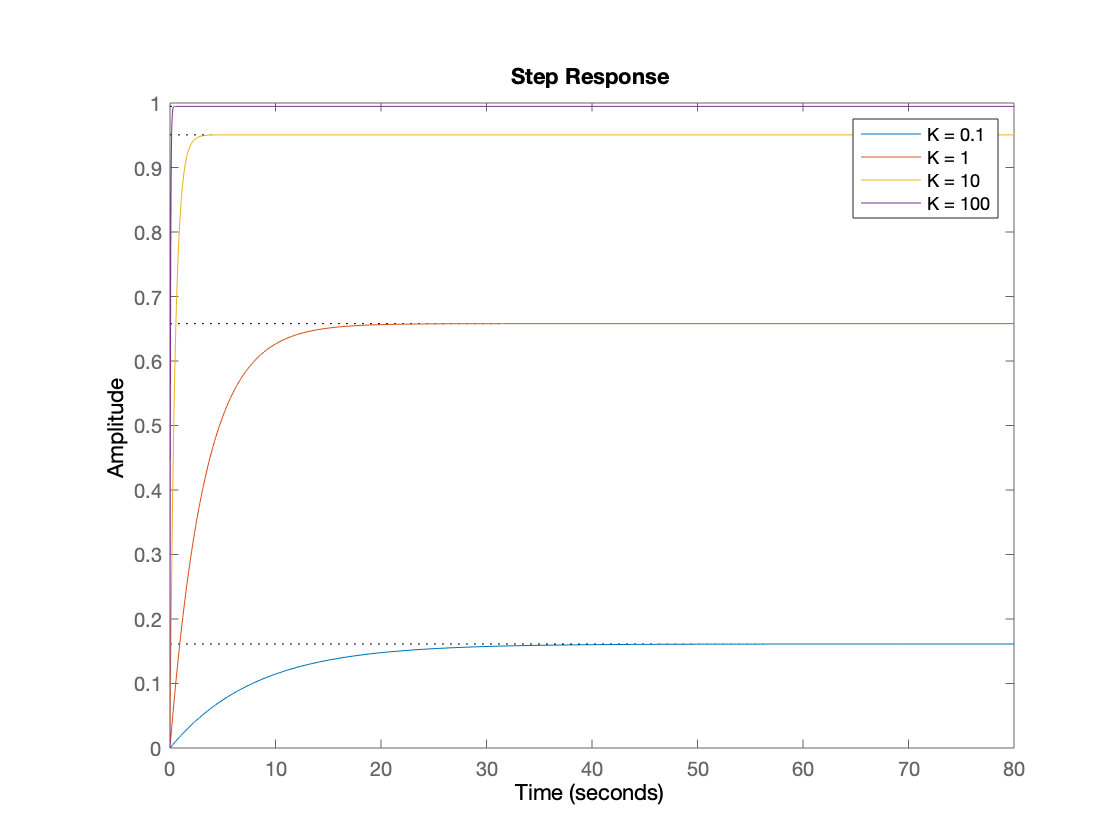

h2 = feedback(G1*K(1,2), 1);
h3 = feedback(G1*K(1,3), 1);
h4 = feedback(G1*K(1,4), 1);

figure (1);
stepplot(h1);
hold on;
stepplot(h2);
stepplot(h3);
stepplot(h4);
legend("K = 0.1", "K = 1", "K = 10","K = 100");
hold off ;

The peak of the response appears to grow exponentially, and the steady state is reached faster as the proportional gain is increased.  This is reflected in each system's rise times and settling times. The time to reach the peak is also decreased with increasing proportional gain. Each system also displays 1st order behavior, as none of the responses have any sinusoidal behavior or overshoot. This makes sense as a proportional gain constant is increases to add stability to the system, which logically, shoot reduce the settling and rise times. 

*8. Consider the transfer function in question 5, repeat steps of question 7 for this system(plot closed loop unity feedback step response). Describe the effect of proportional gain on step response’s behavior [15 marks]. (In this case you should explain the effect of proportional gain on the overshoot, rise-time, and settling time) *

k1 = feedback(G2*K(1,1), 1);
k2 = feedback(G2*K(1,2), 1);
k3 = feedback(G2*K(1,3), 1);
k4 = feedback(G2*K(1,4), 1);

k01_Rise_time = stepinfo(k1).RiseTime

k01_Rise_time = 10.0198

k1_Rise_time = stepinfo(k2).RiseTime

k1_Rise_time = 2.5544

k10_Rise_time = stepinfo(k3).RiseTime

k10_Rise_time = 0.7580

k100_Rise_time = stepinfo(k4).RiseTime

k100_Rise_time = 0.2351


k01_Settling_time = stepinfo(k1).SettlingTime

k01_Settling_time = 76.1727

k1_Settling_time = stepinfo(k2).SettlingTime

k1_Settling_time = 72.2175

k10_Settling_time = stepinfo(k3).SettlingTime

k10_Settling_time = 73.6468

k100_Settliing_time = stepinfo(k4).SettlingTime

k100_Settliing_time = 75.1704


k01_Overshoot = stepinfo(k1).Overshoot 

k01_Overshoot = 28.8756

k1_Overshoot  = stepinfo(k2).Overshoot 

k1_Overshoot = 69.2106

k10_Overshoot = stepinfo(k3).Overshoot 

k10_Overshoot = 89.0836

k100_Overshoot= stepinfo(k4).Overshoot 

k100_Overshoot = 96.4128

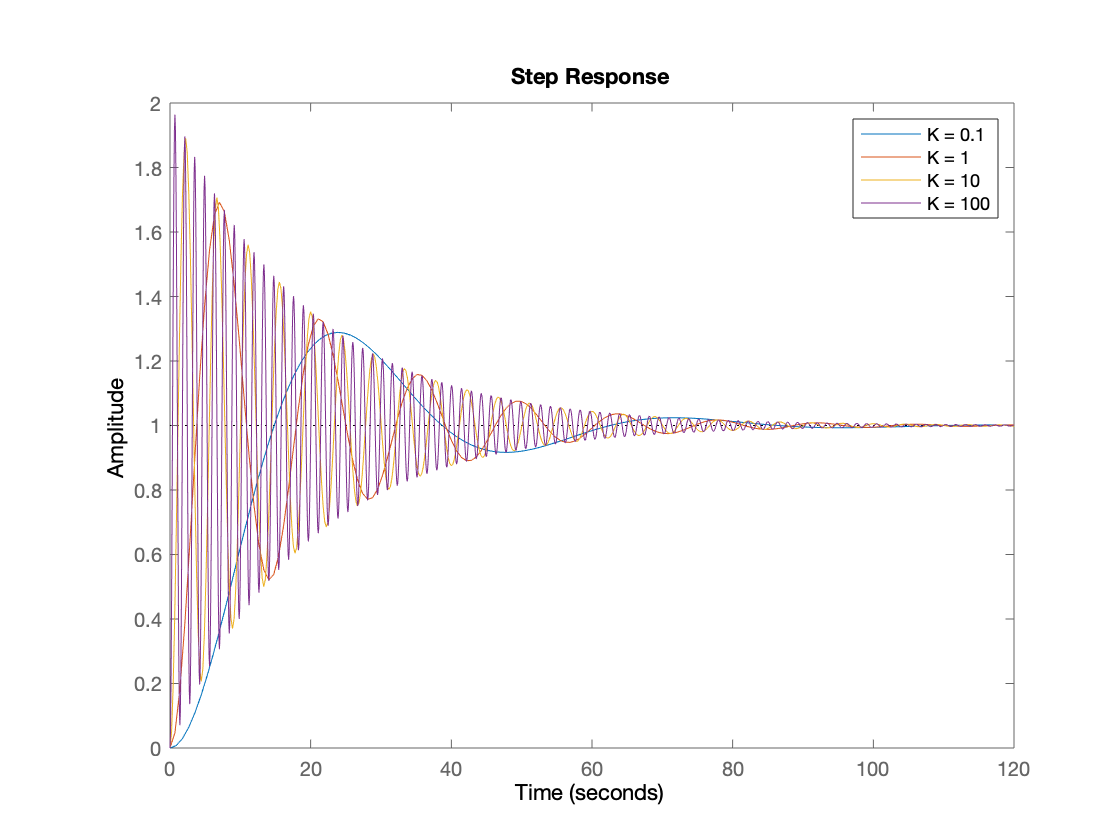



figure (1);
stepplot(k1);
hold on;
stepplot(k2);
stepplot(k3);
stepplot(k4);
legend("K = 0.1", "K = 1", "K = 10","K = 100");
hold off ;

Analysizing the step info, as well as the graph makes it clear that the systems' overshoot increases and the frequency of oscillation decreases considerably as the proportional gain is increased. With the increase in proportional gain also comes considerable decrease in rise time, while settling time remains relatively constant. This can be explained theoretically by the effect of the proportional gain on the closed loop unity feedback transfer function. As proportional gain increases, so does the natural frequency of the underdamped responses on which the peak time depends on inversely. So, natural frequency increases, peak time decreases, leading to an increase in overshoot. Moreover, since settling time depends on the product of the natural frequency and the damping ratio, which remains unchanged by proportional gain changes, the settling time is stable. Finally, rise time (which relates positively to damping ratio) decreases. Since natural frequency increases with proportional gain, damping ratio proportionally decreases, leading to a decrease in rise time. Practically speaking, these results make sense as a proportional gain constant is increases to add stability to the system, which logically, shoot reduce the overshoot and rise times. 